# DSB_main

% DSB_modulation

% T 信号时长
% dt 步长
% 1/t 采样频率
% f_c 载频
% m_t 调制信号
% s_t 已调信号

T = 0.3;
dt = 0.001;
N = T/dt;
t = (0:N-1)*dt;
m_t = sqrt(2)*cos(50*pi*t);
% m_t = exp(-3*t);
fc = 100;
fs = 1/dt;

## 调制

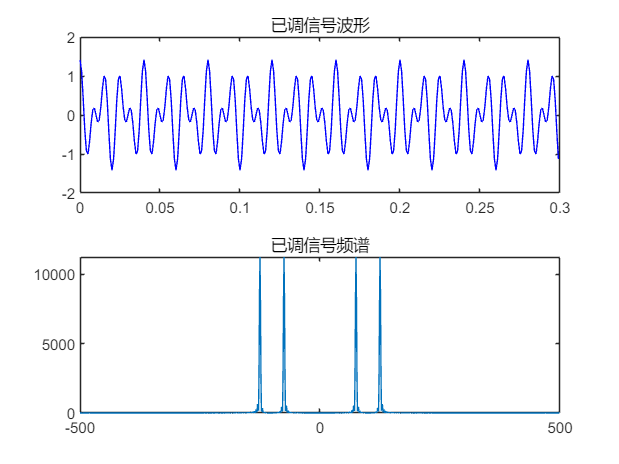

DSB=DSB_modulation(m_t,t,fc);
% 频谱分析
[freq,spectrum]=analyze_spectrum(DSB,fs,1000);
% 图1：调制波形及其频谱
figure(1);
subplot(2,1,1);plot(t,DSB,'b');title('已调信号波形');
subplot(2,1,2);plot(freq,spectrum);title('已调信号频谱');

## 通过信道

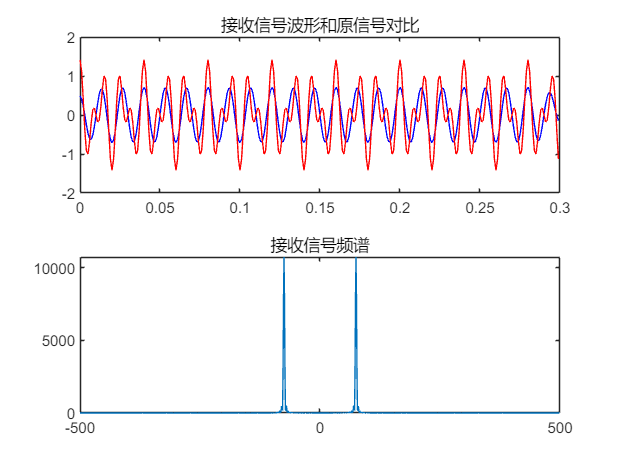

received_signal = channel_simulation(DSB,50, fc, fs);
[freq2,spectrum2]=analyze_spectrum(received_signal,fs,1000);
% 图2：接收到的信号的波形和频谱
figure(2);
subplot(2,1,1);plot(t,received_signal,'b');hold on;plot(t,DSB,'r');hold off;title('接收信号波形和原信号对比');
subplot(2,1,2);plot(freq2,spectrum2);title('接收信号频谱');

## 解调

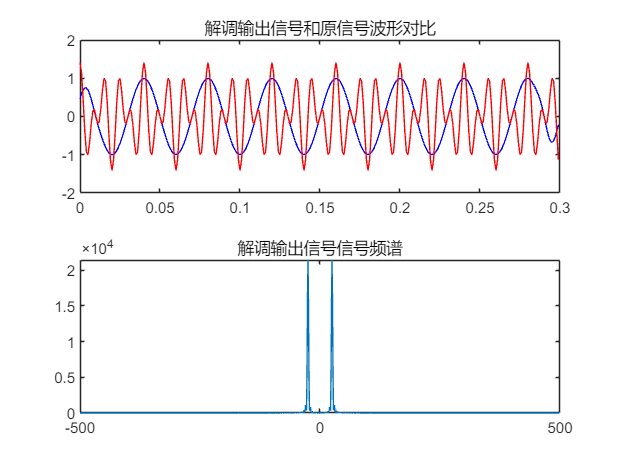

[m_t,mix_t] = Coherent_Demodulation(received_signal,t,fc,fs);
[freq3,spectrum3]=analyze_spectrum(m_t,fs,1000);
% 图3：
figure(3);
subplot(2,1,1);plot(t,m_t,'b');hold on;plot(t,DSB,'r');hold off;title('解调输出信号和原信号波形对比');
subplot(2,1,2);plot(freq3,spectrum3);title('解调输出信号信号频谱');